%RIGHT HEART 
clear; close all; clc

% PARAMETERS (Slide 37). Same as left heart model 
T = 0.0125; % Heart period (min) → 80 bpm
ts = 0.005; % Systole duration (min)
dt = 1e-6; % Time step (must be small!)
tv = 0:dt:25*T; % Simulate 25+ beats

tauS=0.0025; % Systolic time constant
tauD=0.0075; % Diastolic time constant
CRVS=0.00003; % LV systolic compliance (L/mmHg)
CRVD=0.0146; % LV diastolic compliance

Rti=0.01; % Mitral resistance
Rpo=0.01; % Aortic resistance
Rp= 17.5; % Systemic resistance
Cpa=0.001; % Systemic arterial compliance
Ppv=5; % Constant pulmonary venous pressure (right atrial proxy)
Psv=5; %constant systemic venous pressure (right atrial)

% INITIAL CONDITIONS
Psa(1)=100;   
Plv(1)=5;    

Ppa=zeros(size(tv)); Ppa(1)=20;   % Pulmonary arterial pressure
Prv=zeros(size(tv)); Prv(1)=5;    % Right ventricular pressure
Vrv=zeros(size(tv));              % Right ventricular volume (L)

%% PRESSURE-DRIVEN VALVE FUNCTION
valve_open = @(P_up, P_down) double(P_up > P_down);

% Time-varying RV compliance (same function as LV, new parameters)
CRV=@(tt) compute_dynamic_compliance(tt, T, ts, tauS, tauD, CRVS, CRVD);

%% MAIN LOOP – RIGHT HEART ISOLATION
for k = 1:length(tv)-1
    
    % Current and next compliance
    Crv_now  = CRV(tv(k));
    Crv_next = CRV(tv(k+1));
    
    % PRESSURE-DRIVEN VALVES
    S_ti = valve_open(Psv,   Prv(k));   % Tricuspid: open if P_sv > P_RV
    S_po = valve_open(Prv(k), Ppa(k));  % Pulmonic:  open if P_RV > P_pa
    
    % FLOWS (L/min)
    Qti = S_ti * (Psv   - Prv(k)) / Rti;        % Tricuspid inflow
    Qpo = S_po * (Prv(k) - Ppa(k)) / Rpo;       % Pulmonic outflow
    Qp  = (Ppa(k) - Ppv) / Rp;                 % Pulmonary vascular flow
    
    % PULMONARY ARTERIES (ODE)
    dPpa_dt   = (Qpo - Qp) / Cpa;
    Ppa(k+1)  = Ppa(k) + dt * dPpa_dt;
    
    % RIGHT VENTRICLE WITH TIME-VARYING COMPLIANCE
    Prv(k+1)  = (Prv(k) * Crv_now + dt * (Qti - Qpo)) / Crv_next;
    
    % VOLUME FROM PRESSURE
    Vrv(k+1)  = Prv(k+1) * Crv_next;
end

%% PLOTS (25 BEATS)
t_sec = tv * 60;                 % convert min -> s
idx   = 1:round(25*T/dt);       % indices for 25 beats

figure('Position',[100 100 1200 700]);
sgtitle('Right Heart Isolation - Pressure-Driven Valves Only');

% Pulmonary arterial pressure
subplot(2,3,1);
plot(t_sec(idx), Ppa(idx), 'r', 'LineWidth', 1.5); grid on;
title('Pulmonary Arterial Pressure'); ylabel('Pressure (mmHg)');
xlabel('Time (s)');

% Right ventricular pressure
subplot(2,3,2);
plot(t_sec(idx), Prv(idx), 'b', 'LineWidth', 1.5); grid on;
title('Right Ventricular Pressure'); ylabel('Pressure (mmHg)');
xlabel('Time (s)');

% Right ventricular volume
subplot(2,3,3);
plot(t_sec(idx), Vrv(idx)*1000, 'm', 'LineWidth', 1.5); grid on;
title('Right Ventricular Volume'); ylabel('Volume (mL)');
xlabel('Time (s)');

% Mitral flow
subplot(2,3,4);
plot(t_sec(idx), valve_open(Psv, Prv(idx)).*(Psv - Prv(idx))/Rti, 'c'); grid on;
title('Mitral Flow'); ylabel('Flow (L/min)');
xlabel('Time (s)');

% Pulmonic flow
subplot(2,3,5);
plot(t_sec(idx), valve_open(Prv(idx), Ppa(idx)).*(Prv(idx) - Ppa(idx))/Rpo, 'k'); grid on;
title('Aortic Flow'); ylabel('Flow (L/min)');
xlabel('Time (s)');

% RV pressure-volume loop
subplot(2,3,6);
plot(Vrv(idx)*1000, Prv(idx), 'b', 'LineWidth', 2); grid on;
title('RV Pressure–Volume Loop');
xlabel('Volume (mL)'); ylabel('Pressure (mmHg)');

%% Displaying results 
fprintf('Right Heart Model - Steady State:\n\n');

fprintf('Mean Pulmonary Arterial Pressure: %.1f mmHg\n', mean(Ppa(end-5000:end)));

fprintf('RV Peak Pressure: %.1f mmHg\n', max(Prv(end-5000:end)));

stroke_vol = max(Vrv(end-5000:end))*1000 - min(Vrv(end-5000:end))*1000;
fprintf('Stroke Volume: %.1f mL\n', stroke_vol);

% Cardiac output based on pulmonic flow
Qpo_all = valve_open(Prv, Ppa) .* (Prv - Ppa) / Rpo;
fprintf('Cardiac Output: %.2f L/min\n', mean(Qpo_all(end-5000:end)));

% Local function 


function C = compute_dynamic_compliance(t, T, ts, tauS, tauD, Csystolic, Cdiastolic)
    % Time within cardiac cycle
    tc = mod(t, T);

    % Precompute denominators
    denom_systole  = 1 - exp(-ts/tauS);
    denom_diastole = 1 - exp(-(T-ts)/tauD);

    % Systole phase (0 <= tc <= ts)
    in_systole = tc <= ts;
    e_sys = (1 - exp(-(tc(in_systole))/tauS)) ./ denom_systole;
    C_sys = Cdiastolic * (Csystolic / Cdiastolic).^e_sys;

    % Diastole phase (ts < tc < T)
    in_diastole = tc > ts;
    e_dia = (1 - exp(-(tc(in_diastole) - ts)/tauD)) ./ denom_diastole;
    C_dia = Csystolic * (Cdiastolic / Csystolic).^e_dia;

    % Combine
    C = zeros(size(t));
    C(in_systole)  = C_sys;
    C(in_diastole) = C_dia;
end


%%%%%%%%%%%%%%%%%%%%%%%%%% QUESTION 1 %%%%%%%%%%%%%%%%%%%%%%%
%% SYSTEMIC ARTERIAL MODEL – BASELINE vs ARTERIOSCLEROSIS
% Parameters
Psa0= 100; % initial systemic arterial pressure (mmHg)
Rs= 17.5;  % systemic resistance (mmHg/(L/min))
T= 0.0125;  % heart period (min)
ts= 0.005; %systole duration (min)
tmax=0.002;% time max flow (min)
Qmax=14.14;% max aortic flow (L/min)
dt=0.0001; % time step (min)
Csa0= 0.001; %baseline systemic arterial compliance (L/mmHg)
Csa_f= Csa0/2; % arteriosclerosis: reduced by factor of 2

% Time-25 beats
tv=0:dt:25*T;

%% Aortic flow, same 
QAo=zeros(size(tv));
for k = 1:length(tv)-1
    QAo(k) = Qtriangwave(tv(k),Qmax,T,ts,tmax);
end
QAo(end)=QAo(end-1);

%% Baseline simulation, regular Csa
Psa_norm=zeros(size(tv));
Psa_norm(1)=Psa0;

for k = 1:length(tv)-1
    Psa_norm(k+1) = Psa_norm(k) + dt*(QAo(k) - Psa_norm(k)/Rs)/Csa0;
end

Vsa_norm=Csa0 * Psa_norm;
Qs_norm =Psa_norm / Rs;

%% TASK: ARTERIOSCLEROSIS SIMULATION (Csa/2). everything _hard= csa/2
Psa_hard= zeros(size(tv));
Psa_hard(1)= Psa0;

for k = 1:length(tv)-1
    Psa_hard(k+1)= Psa_hard(k) +dt*(QAo(k)- Psa_hard(k)/Rs)/Csa_f;
end

Vsa_hard=Csa_f * Psa_hard;
Qs_hard=Psa_hard / Rs;

%% PRESSURE METRICS FOR LAST HEART BEAT
lastBeatStart =max(tv) - T; %to find when the last heartbeat starts 
idxLast=tv>= lastBeatStart; %to use all the data points for the last heartbeat. 

% Normal
Psyst_norm= max(Psa_norm(idxLast));
Pdiast_norm= min(Psa_norm(idxLast));
Pmean_norm= mean(Psa_norm(idxLast));
Ppulse_norm= Psyst_norm -Pdiast_norm;

% Arteriosclerosis
Psyst_hard= max(Psa_hard(idxLast));
Pdiast_hard= min(Psa_hard(idxLast));
Pmean_hard= mean(Psa_hard(idxLast));
Ppulse_hard= Psyst_hard - Pdiast_hard;

fprintf('\nNORMAL Csa = %.4f L/mmHg\n', Csa0);


NORMAL Csa = 0.0010 L/mmHg


fprintf('Systolic= %.1f mmHg\n', Psyst_norm);

  Systolic  = 60.9 mmHg


fprintf('Diastolic= %.1f mmHg\n', Pdiast_norm);

  Diastolic = 38.4 mmHg


fprintf('Mean= %.1f mmHg\n', Pmean_norm);

  Mean      = 49.4 mmHg


fprintf('Pulse= %.1f mmHg\n', Ppulse_norm);

  Pulse     = 22.4 mmHg



fprintf('\nTask:ARTERIOSCLEROSIS (Csa/2 = %.4f L/mmHg)\n', Csa_f);


ARTERIOSCLEROSIS (Csa/2 = 0.0005 L/mmHg)


fprintf('Systolic= %.1f mmHg\n', Psyst_hard);

  Systolic  = 72.7 mmHg


fprintf('Diastolic= %.1f mmHg\n', Pdiast_hard);

  Diastolic = 28.8 mmHg


fprintf('Mean= %.1f mmHg\n', Pmean_hard);

  Mean      = 49.3 mmHg


fprintf('Pulse= %.1f mmHg\n\n', Ppulse_hard);

  Pulse     = 43.9 mmHg



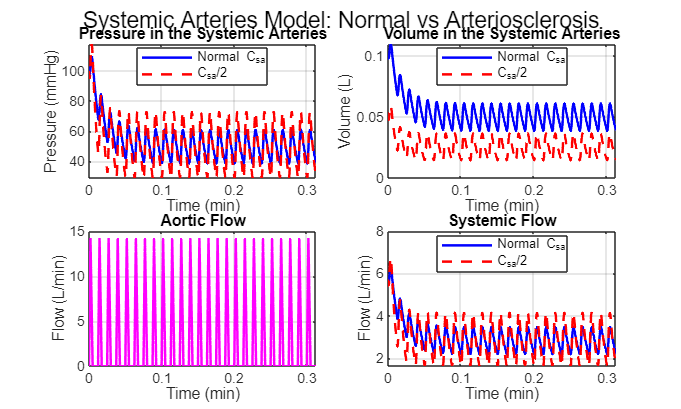


%% Plotting data
figure('Position',[100 100 1000 600]);
sgtitle('Systemic Arteries Model: Normal vs Arteriosclerosis');

% Pressure
subplot(2,2,1);
plot(tv,Psa_norm,'b','LineWidth',1.5); hold on
plot(tv,Psa_hard,'r--','LineWidth',1.5);
grid on
xlabel('Time (min)');
ylabel('Pressure (mmHg)');
title('Pressure in the Systemic Arteries');
legend('Normal C_{sa}','C_{sa}/2','Location','best');

% Volume
subplot(2,2,2);
plot(tv,Vsa_norm,'b','LineWidth',1.5); hold on
plot(tv,Vsa_hard,'r--','LineWidth',1.5);
grid on
xlabel('Time (min)');
ylabel('Volume (L)');
title('Volume in the Systemic Arteries');
legend('Normal C_{sa}','C_{sa}/2','Location','best');

% Aortic flow (same both cases)
subplot(2,2,3);
plot(tv,QAo,'m','LineWidth',1.5);
grid on
xlabel('Time (min)');
ylabel('Flow (L/min)');
title('Aortic Flow');

% Systemic flow
subplot(2,2,4);
plot(tv,Qs_norm,'b','LineWidth',1.5); 
hold on
plot(tv,Qs_hard,'r--','LineWidth',1.5);
grid on
xlabel('Time (min)');
ylabel('Flow (L/min)');
title('Systemic Flow');
legend('Normal C_{sa}','C_{sa}/2','Location','best');

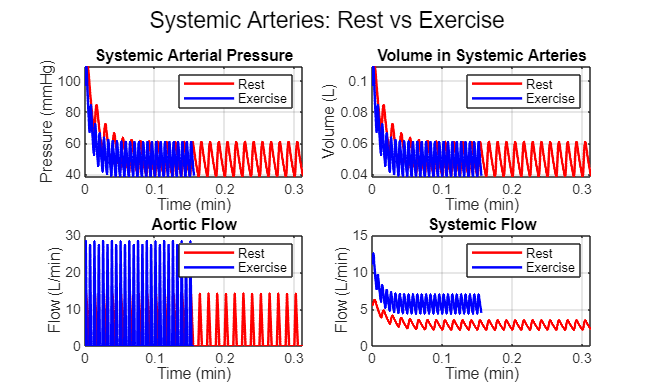

%%%%%%%%%%% Question 2%%%%%%%%%%%%%%
Csa=0.001;     % systemic arterial compliance (L/mmHg)

% Time-25 beats
nBeats=25;
t=0:dt:25*T;


Psa = zeros(size(t));
Psa(1) = Psa0;

for k = 1:length(t)-1
    QAo(k)   = Qtriangwave(t(k),Qmax,T,ts,tmax);
    Psa(k+1) = Psa(k) + dt*(QAo(k) - Psa(k)/Rs)/Csa;
end

Qs  = Psa/Rs;          % systemic flow
Vsa = Csa*Psa;         % arterial volume

%% ---------- EXERCISE ----------
% 1) Reduce systemic resistance by factor of 2
Rs_ex = Rs/2;

% 2) Double heart rate: halve T, ts, tmax
T_ex    = T/2;
ts_ex   = ts/2;
tmax_ex = tmax/2;

% 3) Adjust Qmax to keep stroke volume the same:
%    SV = (1/2)*ts*Qmax  =>  Qmax_ex = Qmax*ts/ts_ex
Qmax_ex = Qmax * ts/ts_ex;   % here = 2*Qmax

t_ex = 0:dt:nBeats*T_ex;

Psa_ex = zeros(size(t_ex));
Psa_ex(1) = Psa0;            % start from same pressure

for k = 1:length(t_ex)-1
    QAo_ex(k)   = Qtriangwave(t_ex(k),Qmax_ex,T_ex,ts_ex,tmax_ex);
    Psa_ex(k+1) = Psa_ex(k) + dt*(QAo_ex(k) - Psa_ex(k)/Rs_ex)/Csa;
end

Qs_ex  = Psa_ex/Rs_ex;
Vsa_ex = Csa*Psa_ex;

%% ---------- PLOTTING ----------
figure('Position',[100 100 1000 600]);
sgtitle('Systemic Arteries: Rest vs Exercise')

% Pressure
subplot(2,2,1)
plot(t,Psa,'r','LineWidth',1.5); hold on
plot(t_ex,Psa_ex,'b','LineWidth',1.5);
grid on
xlabel('Time (min)')
ylabel('Pressure (mmHg)')
title('Systemic Arterial Pressure')
legend('Rest','Exercise')

% Volume
subplot(2,2,2)
plot(t,Vsa,'r','LineWidth',1.5); hold on
plot(t_ex,Vsa_ex,'b','LineWidth',1.5);
grid on
xlabel('Time (min)')
ylabel('Volume (L)')
title('Volume in Systemic Arteries')
legend('Rest','Exercise')

% Aortic flow
subplot(2,2,3)
plot(t(1:end-1),QAo,'r','LineWidth',1.5); hold on
plot(t_ex(1:end-1),QAo_ex,'b','LineWidth',1.5);
grid on
xlabel('Time (min)')
ylabel('Flow (L/min)')
title('Aortic Flow')
legend('Rest','Exercise')

% Systemic flow
subplot(2,2,4)
plot(t,Qs,'r','LineWidth',1.5); hold on
plot(t_ex,Qs_ex,'b','LineWidth',1.5);
grid on
xlabel('Time (min)')
ylabel('Flow (L/min)')
title('Systemic Flow')
legend('Rest','Exercise')

%% Triangle-wave aortic flow function (same as before)
function Q = Qtriangwave(t,Qmax,T,ts,tmax)
t1 = rem(t,T);
for ii = 1:length(t)
    if t1(ii) <= ts               % systole
        if t1(ii) <= tmax         % upstroke
            Q(ii) = Qmax*t1(ii)/tmax;
        else                      % downstroke
            Q(ii) = Qmax*(ts-t1(ii))/(ts-tmax);
        end
    else                          % diastole
        Q(ii) = 0;
    end
end
end
